# **Lecture 2 : Basic MATLAB Programming**

เอกสารประกอบการเรียนการสอนวิชา FRA231 : Robot Modelling and Experimentation

- Credit : [ePix Studio](https://www.youtube.com/watch?v=Ev5WCX4YGqQ&list=PLHnZZE5j6C65tzj59W-BoFbb0cVSk5tdY&index=1) Aj.Pi (Thanacha Choopojcharoen)

- ผู้สอน & จัดทำเอกสาร : อ.กิตติ ธำรงอภิชาตกุล

- ผู้ช่วยปรับปรุงเอกสารประกอบการสอน : ChatGPT 4o

**วัตถุประสงค์การเรียนรู้ (Learning Objectives)**

- **เข้าใจการใช้งานพื้นฐานของ MATLAB**: นักศึกษาจะสามารถใช้งานเมนูบาร์พื้นฐานของ MATLAB ได้อย่างคล่องแคล่ว รวมถึงการจัดการไฟล์และโฟลเดอร์, การตั้งค่าเส้นทาง (Path) ของโปรแกรม และการใช้งาน Command Line Interface สำหรับการสั่งงานต่างๆ

- **สามารถเขียนและรันสคริปต์ MATLAB**: นักศึกษาจะสามารถสร้างและบันทึกสคริปต์ MATLAB ได้ และสามารถเรียกใช้คำสั่งต่างๆ ผ่าน Command Line Interface รวมถึงการจัดการตัวแปรใน Workspace

- **ทำความเข้าใจและประยุกต์การคำนวณด้วยเมทริกซ์**: นักศึกษาจะสามารถสร้างและแก้ไขเวกเตอร์และเมทริกซ์ได้ รวมถึงการดำเนินการทางคณิตศาสตร์กับเมทริกซ์, การคำนวณเชิงตัวเลข และการแก้สมการเชิงเส้นโดยใช้เมทริกซ์

- **สร้างและวิเคราะห์กราฟใน MATLAB**: นักศึกษาจะสามารถสร้างกราฟพื้นฐาน, กราฟที่มีความละเอียดสูงขึ้น และกราฟหลายเส้นในกราฟเดียวกันได้ พร้อมทั้งสามารถวิเคราะห์กราฟและแสดงจุดวิกฤตต่างๆ เช่น จุดต่ำสุด, จุดสูงสุด, และจุดเปลี่ยนเว้าได้

- **เข้าใจการแก้สมการเชิงอนุพันธ์ใน MATLAB**: นักศึกษาจะสามารถแก้สมการเชิงอนุพันธ์สามัญ (ODE) ด้วย MATLAB โดยใช้ฟังก์ชันสำเร็จรูป เช่น `ode45` และสามารถแสดงผลลัพธ์ในรูปแบบกราฟได้

- **สามารถหาค่าเชิงปริพันธ์เชิงสัญลักษณ์และเชิงตัวเลข**: นักศึกษาจะสามารถหาค่าเชิงปริพันธ์ของฟังก์ชันต่างๆ ได้ทั้งในเชิงสัญลักษณ์และเชิงตัวเลข รวมถึงการปริพันธ์ข้อมูลเชิงตัวเลขที่ได้รับจากการวัดหรือคำนวณ

- **พัฒนาแอนิเมชันเพื่อแสดงการเคลื่อนไหวจากผลการคำนวณ**: นักศึกษาจะสามารถสร้างแอนิเมชันเพื่อแสดงผลการคำนวณ เช่น การเคลื่อนที่ของเพนดูลัม ด้วยการใช้ MATLAB และฟังก์ชันการแก้สมการเชิงอนุพันธ์

**หมายเหตุ ****"อนุญาตให้ใช้ในวิชา FRA231 เท่านั้น ห้ามเผยแพร่ก่อนได้รับอนุญาต"**

## **Manu Bar พื้นฐาน**

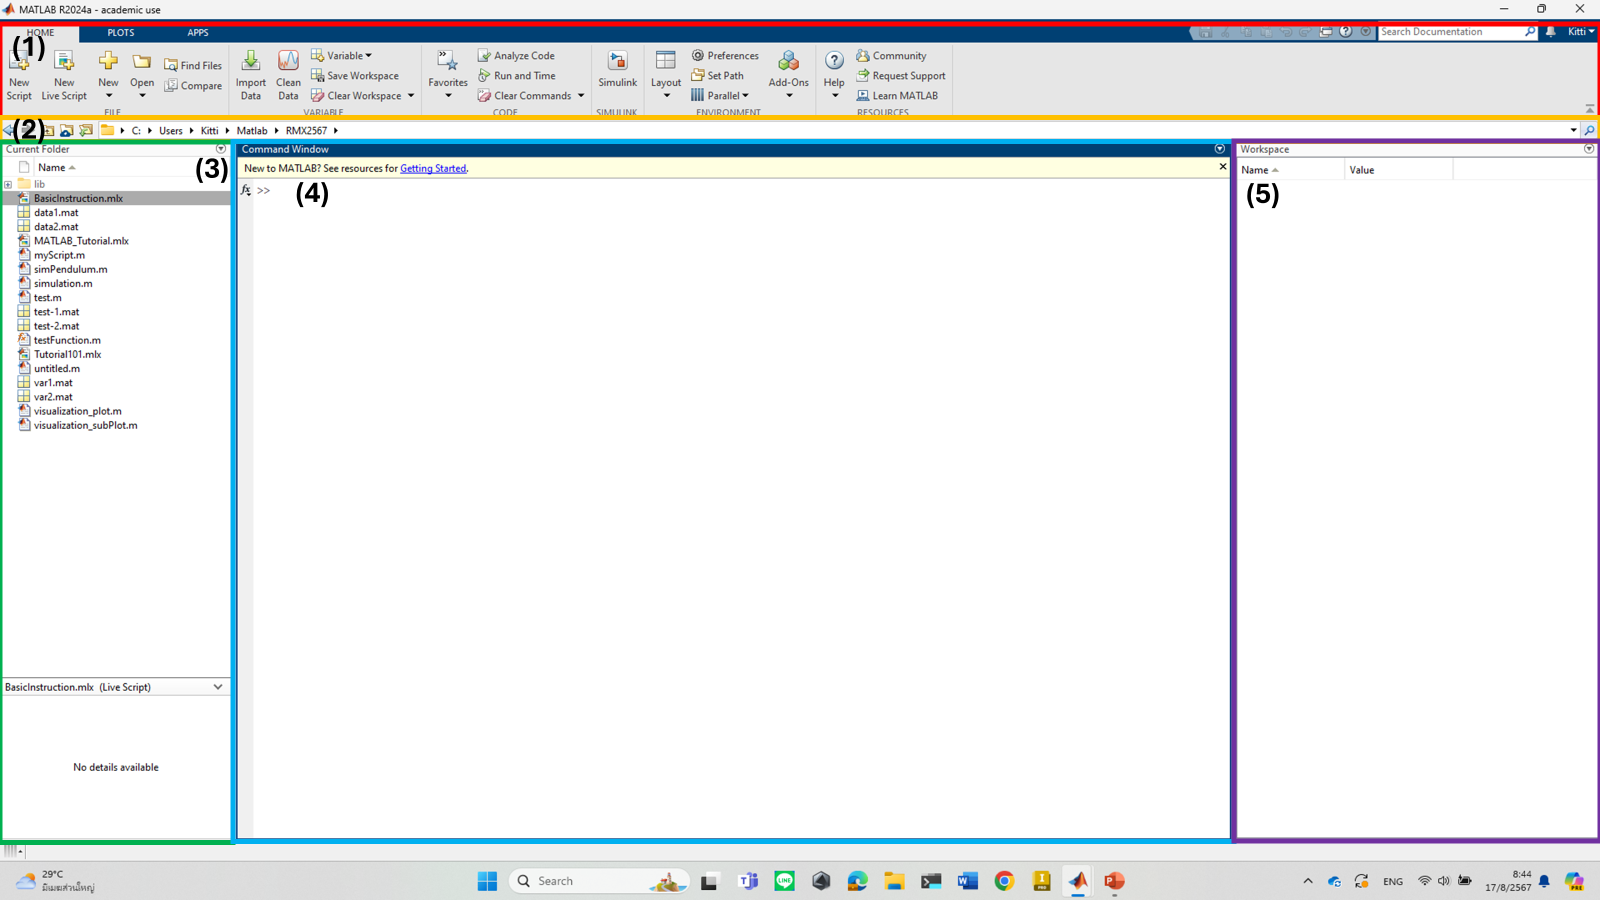

### (1) เกี่ยวข้องกับการจักการฟังก์ชันหลักของโปรแกรม MATLAB

#### HOME

ฟังก์ชันหลักที่ใช้ในการเริ่มต้นใช้งาน MATLAB รวมถึงการจัดการไฟล์และโครงการต่างๆ

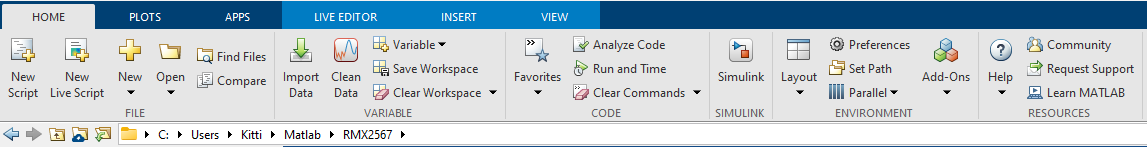

#### APPS

การใช้งานแอปพลิเคชันต่างๆ ใน MATLAB ที่ช่วยในการทำงานเฉพาะทาง

### 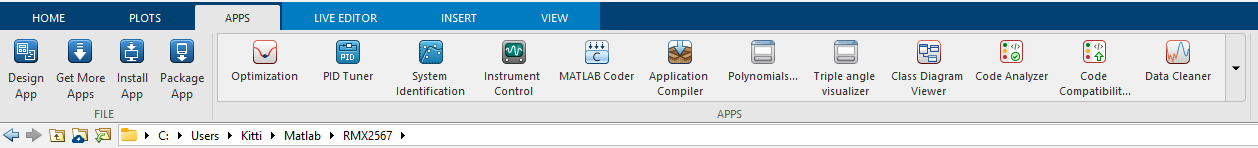

#### LIVE EDITOR

พื้นที่สำหรับการเขียนและทดลองโค้ด MATLAB แบบอินเทอร์แอกทีฟ

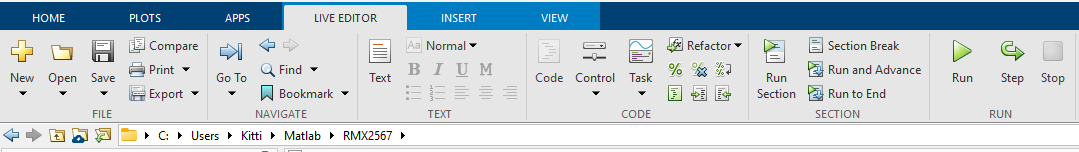

#### INSERT

การแทรกองค์ประกอบต่างๆ เช่น ภาพ ตาราง และกราฟใน Live Script

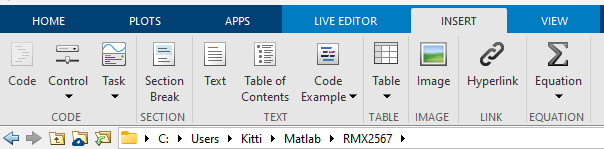

#### VIEW

การจัดการมุมมองและเลย์เอาต์ของหน้าจอการทำงานใน MATLAB

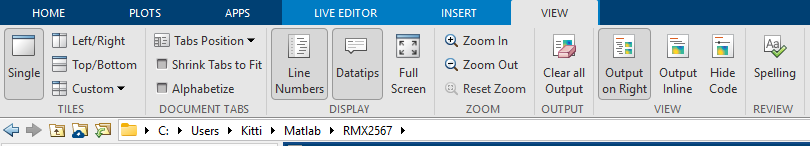

### (2) การจัดการ Path ของโปรแกรม

การเพิ่มหรือลบเส้นทางไฟล์ใน MATLAB เพื่อให้สามารถเรียกใช้ไฟล์ต่างๆ ได้สะดวก

### (3) การจัดการไฟล์และ Folder

คุณสามารถสร้างไฟล์หรือโฟลเดอร์ใหม่ได้จาก HOME tab หรือใช้คำสั่งใน Command Window ตัวอย่าง:

mkdir('NewFolder');
cd('NewFolder');
fid = fopen('NewFile.m', 'w');
fclose(fid);

### (4) การสั่งงานผ่าน Command Line Interface

Command Line Interface (CLI) ของ MATLAB เป็นจุดที่คุณสามารถพิมพ์คำสั่งต่างๆ เพื่อให้ MATLAB รันและแสดงผลลัพธ์ ตัวอย่างเช่น:

a = 3; % การสร้างตัวแปร a
b = 5; % การสร้างตัวแปร b
c = a + b; % การบวก a และ b
disp(c); % แสดงผลลัพธ์

### (5) การจัดการตัวแปรใน Workspace

การดูและจัดการตัวแปรที่มีอยู่ใน Workspace ของ MATLAB

clear; % ลบตัวแปรทั้งหมดใน workspace
who; % แสดงรายการตัวแปรที่อยู่ใน workspace
whos; % แสดงรายการตัวแปรพร้อมข้อมูลเพิ่มเติม

## Operation พื้นฐานใน Command Line Interface

### 1. การขอความช่วยเหลือพื้นฐาน

doc         % สำหรับการอ่านเอกสารและคู่มือการใช้งานของ MATLAB
help        % สำหรับการค้นหาข้อมูลหรือคำอธิบายของฟังก์ชันที่ไม่ทราบ

ตัวอย่างเช่น การใช้ `doc` และ `help` เพื่อค้นหาความช่วยเหลือเกี่ยวกับฟังก์ชันหรือคำสั่งใน MATLAB:

doc plot; % เปิดเอกสารคู่มือของฟังก์ชัน plot
help plot; % แสดงข้อมูลเบื้องต้นเกี่ยวกับฟังก์ชัน plot ใน Command Window

### 2. การจัดการตัวแปรเบื้องต้น

การสร้างตัวแปรและการทำงานทางคณิตศาสตร์เบื้องต้นใน MATLAB เช่น การบวก การคูณ และการใช้ค่าคงที่

a = 3       % การสร้างตัวแปรโดยที่แสดงผลออกมาด้วย
b = 5;      % สร้างตัวแปรโดยที่ไม่ต้องแสดงผลออกมา ให้ใส่ ; ต่อท้าย
c = a + b;  % การบวกระหว่างตัวแปร a และ b
d = a * b;  % การคูณกันระหว่างตัวแปร เราสามารถใช้เครื่องหมา +, - , * , / , ^ ได้ตามปกติเหมือนภาษาคอมพิวเตอร์อื่นๆ
pi          % กการเรียกใช้ค่าคงที่ PI ที่ละเอียด

### 3. คำสั่งในการ Clear Workspace และ Command Windows

clc;        % การล้าง Command Window เพื่อให้หน้าจอสะอาด
clear;      % การล้างตัวแปรทั้งหมดใน Workspace

### 4. การ Save และ Load ตัวแปรใน workspace

การบันทึกตัวแปรลงในไฟล์ `.mat` และการโหลดกลับมาใช้งานใหม่

a = 1;
b = 2;
c = a+b;
% หากต้องการ Save ตัวแปรใน Workspace ให้ใช้คำสั่ง save('ชื่อไฟล์') เช่น
save('var1.mat')
% จากนั้นลองใช้คำสั่ง clear เพื่อทำการล้าง Workspace ทิ้ง
clear;
% ลอง Load ค่าจากไฟล์ var.mat ที่เราทำการ save ไปเมื่อครู่ด้วยคำสั่ง load('ชื่อไฟล์')
load('var1.mat')

### 5. การจัดการไฟล์

**1. สร้าง script ใหม่**

การสร้างสคริปต์ใหม่ใน MATLAB สามารถทำได้ผ่าน GUI หรือผ่านคำสั่งใน Command Window

**ผ่าน GUI:**

- ไปที่ **HOME** tab บนเมนูบาร์ของ MATLAB

- คลิกที่ **New Script** เพื่อสร้างไฟล์สคริปต์ใหม่

- หน้าต่าง Editor จะเปิดขึ้นมาเพื่อให้คุณเขียนโค้ดในสคริปต์นี้

**ผ่าน Command Window:**

edit NewScript.m;

**2. การเพิ่มเส้นทาง (addpath)**

การเพิ่มเส้นทางใน MATLAB จะช่วยให้ MATLAB สามารถเข้าถึงไฟล์ในโฟลเดอร์ต่างๆ ได้โดยไม่ต้องย้ายไฟล์เหล่านั้นไปยังโฟลเดอร์ปัจจุบัน

addpath('C:\Users\Kitti\Matlab\RMX2567\lib');
% คำสั่งนี้จะเพิ่มโฟลเดอร์ MyNewFolder ในไดเรกทอรีที่ระบุเข้าไปในเส้นทางการค้นหา (path) ของ MATLAB

### 6. ฟังก์ชัน sym()

การสร้างตัวเลขเชิงสัญลักษณ์เพื่อหลีกเลี่ยงข้อผิดพลาดจากการประมาณค่าทศนิยม

delta = sym('1/10'); % สร้างตัวเลขเชิงสัญลักษณ์ 1/10
cos(pi/2); % ผลลัพธ์คือ 6.1232e-17 เนื่องจาก pi/2 ถูกประมาณค่า
cos(sym(pi/2)); % ผลลัพธ์เป็น 0

### 7. Logic Operation

การใช้ตัวดำเนินการตรรกศาสตร์พื้นฐาน เช่น มากกว่า น้อยกว่า และการใช้เครื่องหมาย NOT, AND, OR

a1 = 30 > 4; % ผลลัพธ์คือ 1 (จริง)
a2 = 15 <= 3; % ผลลัพธ์คือ 0 (เท็จ)
a2 = ~a2; % ผลลัพธ์คือ 1 (เปลี่ยนเท็จเป็นจริง)
a3 = a2 && true; % ผลลัพธ์คือ 1 (จริง)

## การคำนวณด้วย Matrix

### 1. การสร้าง Vector [ Colum Vector VS Row Vector]

การสร้างเวกเตอร์ทั้งแบบคอลัมน์และแบบแถว

v_a = [1 ; 3 ; 6]; % คอลัมน์เวกเตอร์
v_b = [1 3 6]; % แถวเวกเตอร์
v_b = v_b'; % เปลี่ยนแถวเวกเตอร์เป็นคอลัมน์เวกเตอร์
v_a == v_b; % เปรียบเทียบว่าคอลัมน์เวกเตอร์ทั้งสองเท่ากันหรือไม่
isequal(v_a, v_b)
size(v_a)
% การสร้าง vector
a = 1:10
b = 1:0.5:10
c = 10:-0.1:0   % เริ่มที่ค่า : เพิ่ม/ลดที่ละ * : จนถึงค่า
l = linspace(1, 20, 10)
numel(l)
l = l + 3

### 2. การแก้ไข Vector

v = [1 -3 5]'
v(2)
v(3)
v(3) = 10
disp(v)
v([1;3])        % เลือกตัวที่ 1 กับ 3
v = (0:2:100)'
n = numel(v)
v(end)
v(n)
v(3) = 100
v([1 3 5]) = [112 114 118]
v(end+1) = 102

### 3. การคำนวณด้วย Vector


$$y\left(t\right)=\sin \left(t\right)$$


t = (0:0.1:10)';
y = sin(t);
plot(t, y); % สร้างกราฟเส้นของฟังก์ชัน sine
t_squared = t.^2; % ยกกำลังสองให้กับทุกค่าในเวกเตอร์ t

### 4. การสร้าง Matrix


$$A=\;\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 5\\
8 & 4 & 7 & 4\\
4 & 6 & 2 & 3
\end{array}\right\rbrack$$


size(A) -->  3x4 [row x colum]

A = [1 2 3 5; 8 4 7 4; 4 6 2 3];
A = [[1;8;4] [2;4;6] [3;7;2] [5;4;3] ]
r = 3 % row
c = 5 % colum
zero_matrix = zeros(r,c) % สร้างเมทริกซ์ขนาด 3x4 ที่มีค่าเป็น 0 ทั้งหมด
all(zero_matrix==0, 'all')
% All ones Matrix
B = ones(r,c) % สร้างเมทริกซ์ขนาด 3x4 ที่มีค่าเป็น 1 ทั้งหมด
% Create Ident Matrix
C = eye(3)

### 5. แก้ไข Matrix แบบ 2D

$A=\;\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 5\\
8 & 4 & 7 & 4\\
4 & 6 & 2 & 3
\end{array}\right\rbrack$  --->  $A=\;\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & \left\lbrack 32\right\rbrack \\
\left\lbrack 8\right\rbrack  & 4 & 7 & 4\\
4 & 6 & \left\lbrack 56\right\rbrack  & 3
\end{array}\right\rbrack$

A = [1 2 3 5; 8 4 7 4; 4 6 2 3];
A(1,4) = 32;  % แก้ไขค่าในเมทริกซ์ A ที่ตำแหน่งแถว 1 คอลัมน์ 4 ให้เป็น 32
A(2,1) = 8;   % แก้ไขค่าในเมทริกซ์ A ที่ตำแหน่งแถว 2 คอลัมน์ 1 ให้เป็น 8
A(3,3) = 56;  % แก้ไขค่าในเมทริกซ์ A ที่ตำแหน่งแถว 3 คอลัมน์ 3 ให้เป็น 56

### 6. การดึงค่าของ matrix มาใช้งาน


$$\mathrm{A1}=\;\left\lbrack \begin{array}{cccc}
\left\lbrack 1\right\rbrack  & 2 & 3 & 32\\
\left\lbrack 8\right\rbrack  & 4 & 7 & 4\\
\left\lbrack 4\right\rbrack  & 6 & 56 & 3
\end{array}\right\rbrack$$
  
$$\mathrm{A2}=\;\left\lbrack \begin{array}{cccc}
\left\lbrack 1\right\rbrack  & \left\lbrack 2\right\rbrack  & \left\lbrack 3\right\rbrack  & \left\lbrack 32\right\rbrack \\
8 & 4 & 7 & 4\\
4 & 6 & 56 & 3
\end{array}\right\rbrack$$



$$\textrm{A3}=\;\left\lbrack \begin{array}{cccc}
\left\lbrack 1\right\rbrack  & 2 & 3 & 32\\
\left\lbrack 8\right\rbrack  & 4 & 7 & 4\\
4 & 6 & 56 & 3
\end{array}\right\rbrack$$

$$\textrm{A4}=\;\left\lbrack \begin{array}{cccc}
\left\lbrack 1\right\rbrack  & \left\lbrack 2\right\rbrack  & \left\lbrack 3\right\rbrack  & 32\\
8 & 4 & 7 & 4\\
4 & 6 & 56 & 3
\end{array}\right\rbrack$$

$$\textrm{A5}=\;\left\lbrack \begin{array}{cccc}
1 & \left\lbrack 2\right\rbrack  & \left\lbrack 3\right\rbrack  & 32\\
8 & 4 & 7 & 4\\
4 & 6 & 56 & 3
\end{array}\right\rbrack$$



$$\mathrm{A6}=\;\left\lbrack \begin{array}{cccc}
1 & \left\lbrack 2\right\rbrack  & \left\lbrack 3\right\rbrack  & 32\\
8 & \left\lbrack 4\right\rbrack  & \left\lbrack 7\right\rbrack  & 4\\
4 & 6 & 56 & 3
\end{array}\right\rbrack$$


size(A) -->  3x4 [row x colum]

A = [1 2 3 32; 8 4 7 4; 4 6 56 3];
A1 = A(:,1); % A(:,1) หมายถึง ดึงข้อมูลทุกแถว (:) ในคอลัมน์แรก (1) ของเมทริกซ์ A
A2 = A(1,:); % A(1,:) หมายถึง ดึงข้อมูลทุกคอลัมน์ (:) ในแถวแรก (1) ของเมทริกซ์ A
A3 = A(1:end-1,1); % A(1:end-1,1) หมายถึง ดึงข้อมูลจากแถวแรก (1) จนถึงแถวที่สอง (end-1) ในคอลัมน์แรก (1)
A4 = A(1,1:end-1); % A(1,1:end-1) หมายถึง ดึงข้อมูลจากแถวแรก (1) ในคอลัมน์แรก (1) จนถึงคอลัมน์ที่สาม (end-1)
A5 = A(1,2:3); % A(1,2:3) หมายถึง ดึงข้อมูลจากแถวแรก (1) ในคอลัมน์ที่ 2 ถึง 3 (2:3)
A6 = A(1:2, 2:3); % A(1:2, 2:3) หมายถึง ดึงข้อมูลจากแถวที่ 1 ถึง 2 (1:2) ในคอลัมน์ที่ 2 ถึง 3 (2:3)
A(7); % A(7) จะคืนค่า 6 (ซึ่งคือค่าในตำแหน่งที่ 7 ของเมทริกซ์ที่ถูกมองว่าเป็นเวกเตอร์)

### 7. การสร้าง Tensor ใน 3 มิติ

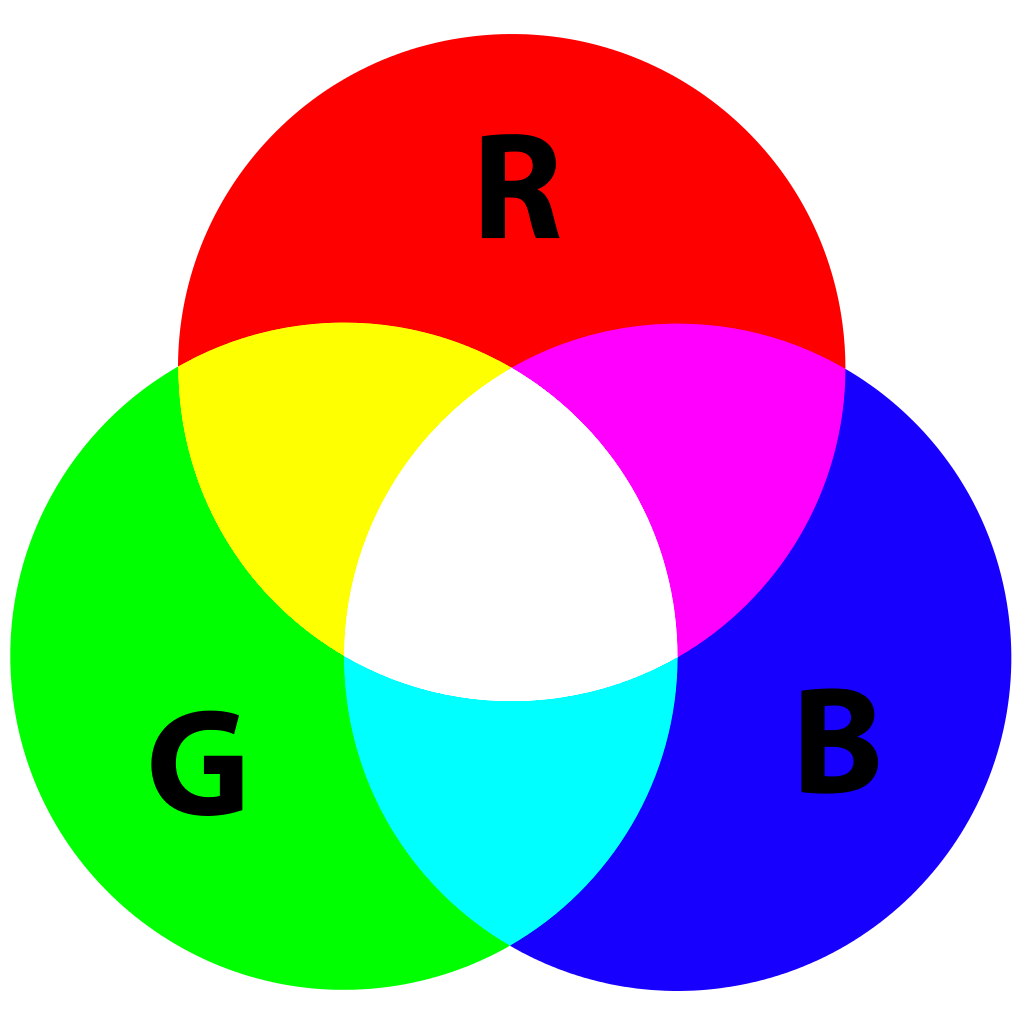

การสร้าง Tensor ใน 3 มิติใน MATLAB เป็นการจัดการกับข้อมูลที่มีหลายมิติ (เกินกว่า 2 มิติ) เช่น การสร้างภาพสีที่มี 3 ช่องสี (Red, Green, Blue - RGB) ซึ่งใน MATLAB จะถูกจัดเก็บในรูปแบบ Tensor ขนาด 3 มิติ

O = ones(100); % สร้างเมทริกซ์ขนาด 100x100 ที่มีค่าทั้งหมดเป็น 1
Z = zeros(100); % สร้างเมทริกซ์ขนาด 100x100 ที่มีค่าทั้งหมดเป็น 0
R = [O Z Z O; O O Z Z]; % สร้างเมทริกซ์ขนาด 200x400 ที่ประกอบด้วยเมทริกซ์ขนาด 100x100 ที่ประกอบด้วย O (1) และ Z (0) ในตำแหน่งที่ต่างกัน เพื่อใช้เป็นข้อมูลในช่องสีแดง
G = [Z O Z O; O Z O Z]; % สร้างเมทริกซ์ขนาด 200x400 ที่ประกอบด้วยเมทริกซ์ขนาด 100x100 สำหรับข้อมูลในช่องสีเขียว โดยมีรูปแบบการวาง O และ Z ที่ต่างไปจากช่องสีแดง
B = [Z Z O O; Z O O Z]; % สร้างเมทริกซ์ขนาด 200x400 ที่ประกอบด้วยเมทริกซ์ขนาด 100x100 สำหรับข้อมูลในช่องสีน้ำเงิน
I = cat(3,R,G,B); % ใช้ฟังก์ชัน cat เพื่อรวมเมทริกซ์ R, G, และ B ในแนวที่ 3 (สร้าง Tensor 3 มิติ) เพื่อสร้างภาพสี
image(I) % ใช้ฟังก์ชัน image เพื่อแสดง Tensor 3 มิติที่สร้างขึ้นในรูปแบบของภาพ
axis equal % การตั้งค่าให้แกน x และ y มีสัดส่วนที่เท่ากัน

### 8. การคำนวณด้วย Matrix

การคำนวณด้วยเมทริกซ์ (Matrix) ใน MATLAB เป็นพื้นฐานที่สำคัญสำหรับการทำงานทางคณิตศาสตร์ต่างๆ ในหลายสาขาวิชา เช่น การวิเคราะห์ข้อมูล การประมวลผลสัญญาณ และการควบคุมระบบ


$$A=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack$$



$$B=\left\lbrack \begin{array}{cc}
1 & 5\\
2 & 6\\
3 & 7\\
4 & 8
\end{array}\right\rbrack$$



$$C=\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack$$


A = [1 2 3 4; 2 4 6 8; 3 6 9 12]; % A เป็นเมทริกซ์ขนาด 3x4
B = [1 5; 2 6; 3 7; 4 8]; % B เป็นเมทริกซ์ขนาด 4x2
C = [1; -1]; % C เป็นเวกเตอร์คอลัมน์ขนาด 2x1
% A*B [3x4] [4x2] -> [3x2]
% B*A --> X


$$A*B=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 5\\
2 & 6\\
3 & 7\\
4 & 8
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
30 & 70\\
60 & 140\\
90 & 210
\end{array}\right\rbrack$$


การคูณ `A*B` เป็นการคูณเมทริกซ์มาตรฐาน (matrix multiplication) ที่เป็นไปได้เมื่อจำนวนคอลัมน์ของ `A` ตรงกับจำนวนแถวของ `B`.

`A` มีขนาด 3x4 และ `B` มีขนาด 4x2 ดังนั้น `A*B` จะให้ผลลัพธ์เป็นเมทริกซ์ขนาด 3x2:

result_AB = A * B; 
result_BA = B * A; % จะเกิดข้อผิดพลาด
% การคูณ B*A จะทำให้เกิดข้อผิดพลาด เนื่องจากจำนวนคอลัมน์ของ B (2) ไม่เท่ากับจำนวนแถวของ A (3)
% ในการคูณเมทริกซ์นั้น เงื่อนไขที่ต้องตรงกันคือ จำนวนคอลัมน์ของเมทริกซ์แรกต้องเท่ากับจำนวนแถวของเมทริกซ์ที่สอง.

### 9. การแก้สมการหลายตัวแปรด้วย Matrix

การแก้สมการหลายตัวแปรด้วยเมทริกซ์ (Matrix) เป็นวิธีที่มีประสิทธิภาพในการหาคำตอบของสมการเชิงเส้นหลายตัวแปร ใน MATLAB สามารถใช้เมทริกซ์ในการแก้สมการเชิงเส้นได้อย่างสะดวกสบาย โดยใช้วิธีการต่างๆ เช่น การใช้ตัวดำเนินการแบ็คสแลช (`\`) หรือการหาผลคูณของเมทริกซ์ผกผัน (inverse) กับเวกเตอร์ผลลัพธ์

**ตัวอย่างการแก้สมการโดยใช้ Matrix**

เรามีระบบสมการเชิงเส้นดังนี้


$$\begin{array}{l}
2x+y-z=1\\
x+z=2\\
2y+2z=1
\end{array}$$


สามารถเขียนในรูปของเมทริกซ์ได้เป็น


$$\textrm{Ax}=c$$


โดยที่


$$A=\;\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack \;,c=\left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack$$


เราสามารถหาค่าของ $x$ ได้จากการ Inverse Matrix A

ดังนี้


$$x=A^{-1} c$$


เมื่อแทนค่าในสมการจะได้


$$\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack$$


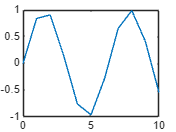

A = [2 1 -1; 1 0 1; 0 2 2];
c = [1; 2; 1];
x = A\c;
x = inv(A)*c;

%A^2 vs A.^2
A_squared = A^2; % ยกกำลังสองของเมทริกซ์ A
element_wise_squared = A.^2; % ยกกำลังสองแบบองค์ประกอบ (element-wise) ของเมทริกซ์ A

At = A'; % Transpost เมทริกซ์ A (สลับแถวและคอลัมน์)
detA = det(A); % หาค่าดีเทอร์มิแนนท์ของเมทริกซ์ A

## Visualization

การทำ Visualization ใน MATLAB เป็นส่วนสำคัญในการนำเสนอข้อมูลหรือผลลัพธ์จากการคำนวณในรูปแบบของกราฟหรือภาพเคลื่อนไหว เพื่อให้เข้าใจได้ง่ายขึ้น ต่อไปนี้จะเป็นการอธิบายและตัวอย่างโค้ดสำหรับการสร้างกราฟ การสร้างกราฟหลายเส้นในกราฟเดียวกัน การแก้สมการเชิงอนุพันธ์ และการสร้างแอนิเมชัน

### **1. การสร้างกราฟพื้นฐาน**

เริ่มต้นด้วยการสร้างกราฟของฟังก์ชัน sine โดยใช้ช่วงของค่า `t` และ `y`

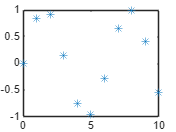

t = (0:10)';

y = sin(t);
plot(t, y); % สร้างกราฟเส้นของฟังก์ชัน sine

% เพิ่มจุดลงในกราฟ
plot(t, y, '*'); % สร้างกราฟเส้นพร้อมแสดงจุด

### **2. การสร้างกราฟที่มีการคำนวณละเอียดขึ้น**

เพิ่มความละเอียดในการคำนวณ โดยใช้ช่วงของ `t` ที่มีค่าละเอียดขึ้น

t1 = (0:0.1:10)';
y1 = sin(t1);
plot(t1, y1, '*'); % สร้างกราฟพร้อมแสดงจุดในช่วงที่ละเอียดขึ้น
% t1 มีช่วงค่าที่ละเอียดขึ้นจาก 0 ถึง 10 โดยเพิ่มทีละ 0.1.

### 3. การสร้างกราฟหลายเส้นในกราฟเดียวกัน

การสร้างกราฟหลายเส้นในกราฟเดียวกันและการกำหนดรูปแบบของเส้นและสี

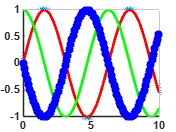

t = (0:0.1:10)';
y = [sin(t) cos(t) -sin(t)]; % ฟังก์ชัน sine, cosine และ -sine
ax = axes;
hold(ax, "on"); % คงกราฟเดิมไว้เพื่อวาดกราฟใหม่ทับ
plot(t, y); % สร้างกราฟหลายเส้นในกราฟเดียวกัน

% กำหนดสีและรูปแบบของเส้น
c = 'rgb'; % สี: แดง, เขียว, น้ำเงิน
s = ['--', '**', '-*']; % รูปแบบของเส้น: เส้นประ, จุด, เส้นประพร้อมจุด
for i = 1:size(y, 2)
    plot(ax, t, y(:, i), [c(i) s(i)], 'LineWidth', 2); % วาดกราฟแต่ละเส้นด้วยสีและรูปแบบที่กำหนด
end

ฟังก์ชัน `hold(ax, "on")` ใช้สำหรับการวาดหลายกราฟในกราฟเดียวกัน

ใช้ `for` loop เพื่อวาดแต่ละกราฟด้วยสีและรูปแบบที่แตกต่างกัน

### 4. การสร้างกราฟแบบ subplot

t = (0:0.1:10)'; % กำหนดเวลา t จาก 0 ถึง 10 วินาที โดยเพิ่มทีละ 0.1
y = [sin(t) cos(t) -sin(t)]; % สร้างฟังก์ชัน y = sin(t), cos(t), และ -sin(t)

ax_1 = subplot(2,2,[1 3]); % กราฟที่ 1 ครอบคลุมช่อง 1 และ 3
ax_2 = subplot(2,2,2); % กราฟที่ 2 ในช่อง 2
ax_3 = subplot(2,2,4); % กราฟที่ 3 ในช่อง 4

ax = [ax_1;ax_2;ax_3]; % รวมเอา subplot ทั้ง 3 เข้าด้วยกันในอาร์เรย์
unit = ["m" "m/s" "m/s^2"]; % หน่วยที่แตกต่างกันสำหรับแต่ละกราฟ
c = 'rgb'; % กำหนดสีสำหรับแต่ละกราฟ

for i = 1:size(y,2)
    plot(ax(i), t, y(:,i), [c(i) '--'], 'LineWidth', 2); % วาดกราฟในแต่ละ subplot
    grid(ax(i), 'on'); % เปิดกริดในแต่ละกราฟ
    xticks(ax(i), 0:2:t(end)); % กำหนดตำแหน่งของ ticks บนแกน x
    xlabel(ax(i), 'time [$s$]', 'FontSize',14, 'Interpreter','latex'); % ชื่อแกน x พร้อมหน่วย
    ylabel(ax(i), "y [" + unit(i) + "]"); % ชื่อแกน y พร้อมหน่วยที่แตกต่างกัน
    legend(ax(i), 'y','dy/dt','d^2y/dt^2'); % ใส่ legend ในแต่ละกราฟ
end

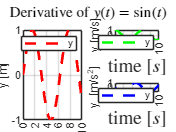


sgtitle('Derivative of $y(t)=\sin(t)$', 'Interpreter','latex'); % ชื่อกราฟทั้งหมด

**ผลลัพธ์:**

โค้ดนี้จะสร้างกราฟ 3 กราฟในหนึ่งหน้า โดยมีการจัดวางดังนี้:

- กราฟที่ 1 ซึ่งเป็น $\sin \left(t\right)$ จะถูกวาดบนช่องที่ครอบคลุมตำแหน่งที่ 1 และ 3 ของตาราง 2x2

- กราฟที่ 2 $\cos \left(t\right)$ จะถูกวาดบนช่องที่ 2

- กราฟที่ 3 $-\sin \left(t\right)$ จะถูกวาดบนช่องที่ 4

## การหาอนุพันธ์

การแก้ไขปัญหาทางแคลคูลัสใน MATLAB สามารถทำได้โดยการใช้ฟังก์ชันต่างๆ ที่เกี่ยวข้องกับการหาอนุพันธ์ การหาจุดวิกฤต (critical points) และการวิเคราะห์ลักษณะของกราฟ เช่น การหาจุดต่ำสุด สูงสุด การวิเคราะห์ความโค้ง และจุดเปลี่ยนเว้า (inflection points) ต่อไปนี้เป็นตัวอย่างวิธีการต่างๆ:


$$f\left(x\right)=x^3 -3x^2 +4$$


### 1. **การหาจุดต่ำสุด (Minimum) และจุดสูงสุด (Maximum)**

ใช้ฟังก์ชัน `fminbnd` หรือ `fminsearch` สำหรับหาจุดต่ำสุด และ `fminbnd` ร่วมกับการกลับเครื่องหมายของฟังก์ชันเพื่อหาจุดสูงสุด

f = @(x) x^3 - 3*x^2 + 4;

% หาจุดต่ำสุดในช่วงที่กำหนด [0, 3]
min_value = fminbnd(f, 0, 3);
disp(['Minimum value: ', num2str(min_value)]);

% หาจุดสูงสุดในช่วงที่กำหนด [0, 3] โดยใช้ฟังก์ชัน -f(x)
max_value = fminbnd(@(x) -f(x), 0, 3);
disp(['Maximum value: ', num2str(-max_value)]);

### 2. **การหาค่าอนุพันธ์ (Derivative) และการวิเคราะห์กราฟ**

หากต้องการหาค่าอนุพันธ์โดยตรง MATLAB มีฟังก์ชัน `diff` สำหรับการหาค่าอนุพันธ์ของข้อมูล

syms x;
f = x^3 - 3*x^2 + 4;

% หาอนุพันธ์แรกt = (0:0.1:10)'; % กำหนดเวลา t จาก 0 ถึง 10 วินาที โดยเพิ่มทีละ 0.1
y = [sin(t) cos(t) -sin(t)]; % สร้างฟังก์ชัน y = sin(t), cos(t), และ -sin(t)

ax_1 = subplot(2,2,[1 3]); % กราฟที่ 1 ครอบคลุมช่อง 1 และ 3
ax_2 = subplot(2,2,2); % กราฟที่ 2 ในช่อง 2
ax_3 = subplot(2,2,4); % กราฟที่ 3 ในช่อง 4

ax = [ax_1;ax_2;ax_3]; % รวมเอา subplot ทั้ง 3 เข้าด้วยกันในอาร์เรย์
unit = ["m" "m/s" "m/s^2"]; % หน่วยที่แตกต่างกันสำหรับแต่ละกราฟ
c = 'rgb'; % กำหนดสีสำหรับแต่ละกราฟ

for i = 1:size(y,2)
    plot(ax(i), t, y(:,i), [c(i) '--'], 'LineWidth', 2); % วาดกราฟในแต่ละ subplot
    grid(ax(i), 'on'); % เปิดกริดในแต่ละกราฟ
    xticks(ax(i), 0:2:t(end)); % กำหนดตำแหน่งของ ticks บนแกน x
    xlabel(ax(i), 'time [$s$]', 'FontSize',14, 'Interpreter','latex'); % ชื่อแกน x พร้อมหน่วย
    ylabel(ax(i), "y [" + unit(i) + "]"); % ชื่อแกน y พร้อมหน่วยที่แตกต่างกัน
    legend(ax(i), 'y','dy/dt','d^2y/dt^2'); % ใส่ legend ในแต่ละกราฟ
end

sgtitle('Derivative of $y(t)=\sin(t)$', 'Interpreter','latex'); % ชื่อกราฟทั้งหมด
f_prime = diff(f, x);
disp(['First derivative: ', char(f_prime)]);

% หาอนุพันธ์ที่สอง
f_double_prime = diff(f_prime, x);
disp(['Second derivative: ', char(f_double_prime)]);
% diff ใช้สำหรับหาค่าอนุพันธ์ของฟังก์ชันที่นิยามในรูปแบบเชิงสัญลักษณ์

### 3. **การหาจุดเปลี่ยนเว้า (Inflection Point)**

ใช้ `fzero` ร่วมกับอนุพันธ์ที่สองเพื่อหาจุดเปลี่ยนเว้า

% หาอนุพันธ์ที่สอง
f_double_prime_func = matlabFunction(f_double_prime);

% หา inflection point โดยใช้ fzero
inflection_point = fzero(f_double_prime_func, 0);
disp(['Inflection point: ', num2str(inflection_point)]);

### 4. **การวิเคราะห์กราฟด้วย **`fplot`

ใช้ `fplot` เพื่อวิเคราะห์กราฟของฟังก์ชันอย่างง่ายโดยไม่ต้องคำนวณเอง

fplot(f, [-2, 4]); % แสดงกราฟของฟังก์ชัน f ในช่วง -2 ถึง 4
grid on; % เปิดเส้นตารางในกราฟ
title('Graph of f(x) = x^3 - 3x^2 + 4');
xlabel('x');
ylabel('f(x)');

### 5. วาดกราฟและแสดงจุดต่ำสุด จุดสูงสุด และจุดเปลี่ยนเว้า

% กำหนด anonymous ฟังก์ชัน
f = @(x) x^3 - 3*x^2 + 4;

% หาอนุพันธ์แรกและอนุพันธ์ที่สอง
syms x;
f_prime = diff(f(x), x);
f_double_prime = diff(f_prime, x);

% หา critical points (จุดต่ำสุด/สูงสุด) โดยแก้ f'(x) = 0
critical_points = double(solve(f_prime == 0, x));

% หา inflection point โดยแก้ f''(x) = 0
inflection_point = double(solve(f_double_prime == 0, x));

% หาค่าของฟังก์ชันที่จุดวิกฤตและจุดเปลี่ยนเว้า
min_value = fminbnd(f, -2, 3); % ค้นหาค่าต่ำสุดในช่วง -2 ถึง 3
max_value = fminbnd(@(x) -f(x), 0, 3); % ค้นหาค่าสูงสุดโดยกลับเครื่องหมาย
max_value = -max_value; % กลับเครื่องหมายกลับมาคืน

y_min = f(min_value);
y_max = f(max_value);
y_inflection = f(inflection_point);

% วาดกราฟของฟังก์ชัน
fplot(f, [-2, 4], 'LineWidth', 2); % แสดงกราฟของฟังก์ชันในช่วง -2 ถึง 4
grid on; % เปิดเส้นตารางในกราฟ
hold on; % คงกราฟเดิมไว้เพื่อวาดกราฟใหม่ทับ
xlabel('x');
ylabel('f(x)');
title('Graph of f(x) = x^3 - 3x^2 + 4 with Critical and Inflection Points');

% วาดตำแหน่งจุดต่ำสุด
plot(min_value, y_min, 'ro', 'MarkerSize', 10, 'DisplayName', 'Minimum');

% วาดตำแหน่งจุดสูงสุด
plot(max_value, y_max, 'go', 'MarkerSize', 10, 'DisplayName', 'Maximum');

% วาดตำแหน่งจุดเปลี่ยนเว้า
plot(inflection_point, y_inflection, 'bo', 'MarkerSize', 10, 'DisplayName', 'Inflection Point');

% แสดงคำอธิบายต่างๆ ลงบนกราฟ
legend show;

hold off; % ปิดการถือครองกราฟเพื่อวาดกราฟใหม่

## **การแก้สมการเชิงอนุพันธ์สามัญ (ODE) แบบง่าย**

การแก้สมการเชิงอนุพันธ์ (Differential Equation) ใน MATLAB สามารถทำได้หลายวิธีขึ้นอยู่กับประเภทของสมการและเงื่อนไขเริ่มต้นที่มีอยู่ ตัวอย่างที่พบบ่อยที่สุดคือการใช้ตัวแก้สมการเชิงอนุพันธ์ เช่น `ode45` ซึ่งใช้วิธีการ Runge-Kutta ในการแก้สมการเชิงอนุพันธ์สามัญ (Ordinary Differential Equations, ODEs)

เราสามารถแก้สมการเชิงอนุพันธ์ดังต่อไปนี้:


$$\frac{\textrm{dy}}{\textrm{dt}}=-2y+e^{-t}$$


**ขั้นตอนการแก้สมการใน MATLAB:**

- นิยามฟังก์ชันสมการเชิงอนุพันธ์

- กำหนดเงื่อนไขเริ่มต้น (Initial Condition)

- เรียกใช้ `ode45` เพื่อแก้สมการ

- แสดงผลลัพธ์ในรูปแบบกราฟ

### **1. นิยามฟังก์ชันสมการเชิงอนุพันธ์**

ใน MATLAB คุณสามารถนิยามสมการเชิงอนุพันธ์ได้โดยใช้ฟังก์ชันนิรนาม (anonymous function):

dydt = @(t, y) -2*y + exp(-t);
% @(t, y) เป็นการบอกว่า dydt เป็นฟังก์ชันของตัวแปร t และ y
%-2*y + exp(-t) คือสมการเชิงอนุพันธ์ที่กำหนด

### **2. กำหนดเงื่อนไขเริ่มต้น**

กำหนดค่าเริ่มต้นที่ `t = 0` และ `y = 1` (ค่าที่ให้ไว้หรือกำหนดเอง):

y0 = 1; % ค่าเริ่มต้นของ y เมื่อ t = 0
tspan = [0 5]; % ช่วงเวลาที่ต้องการหาคำตอบ

### **3. เรียกใช้ **`ode45`** เพื่อแก้สมการ**

ใช้ `ode45` ซึ่งเป็นตัวแก้สมการเชิงอนุพันธ์ที่มีอยู่ใน MATLAB:

[t, y] = ode45(dydt, tspan, y0);
% ode45 จะคืนค่าผลลัพธ์เป็น t และ y ซึ่งเป็นเวกเตอร์ของค่าที่ t และค่าของ y ที่คำนวณได้ในช่วง tspan

### **4. แสดงผลลัพธ์ในรูปแบบกราฟ**

แสดงผลลัพธ์ในรูปแบบกราฟเพื่อดูการเปลี่ยนแปลงของ `y` ตามค่า `t`:

plot(t, y, '-o');
xlabel('t');
ylabel('y(t)');
title('Solution of dy/dt = -2y + e^{-t} using ode45');
grid on;

## การหาค่าเชิงปริพันธ์ (Integration)

การหาค่าเชิงปริพันธ์ (Integration) ใน MATLAB สามารถทำได้ทั้งในเชิงสัญลักษณ์และเชิงตัวเลข ขึ้นอยู่กับลักษณะของปัญหาที่คุณต้องการแก้ ต่อไปนี้จะเป็นตัวอย่างการหาค่าเชิงปริพันธ์ในทั้งสองวิธี:

### 1. **การหาค่าเชิงปริพันธ์เชิงสัญลักษณ์ (Symbolic Integration)**

ในการหาค่าเชิงปริพันธ์เชิงสัญลักษณ์ คุณสามารถใช้ฟังก์ชัน `int` ของ MATLAB โดยที่คุณต้องใช้ Symbolic Math Toolbox

**ตัวอย่าง: หาค่าเชิงปริพันธ์ของฟังก์ชัน **$f\left(x\right)=x^2 +3x+2$

syms x; % กำหนดให้ x เป็นตัวแปรเชิงสัญลักษณ์
f = x^2 + 3*x + 2; % กำหนดฟังก์ชัน
F = int(f, x); % หาค่าเชิงปริพันธ์ของ f(x) ตามตัวแปร x
disp(F);

ผลลัพธ์คือปริพันธ์ของ $f\left(x\right)$ ซึ่งคือ:


$$F\left(x\right)=\frac{x^3 }{3}+\frac{3x^2 }{2}+2x+C$$


**การหาค่าเชิงปริพันธ์แบบจำกัดขอบเขต**

หากค้องการหาค่าเชิงปริพันธ์แบบจำกัดขอบเขต (Definite Integral) เช่น จาก `a` ถึง `b`:

F_definite = int(f, x, 0, 2); % หาค่าเชิงปริพันธ์จาก 0 ถึง 2
disp(F_definite);

### **2. การหาค่าเชิงปริพันธ์เชิงตัวเลข (Numerical Integration)**

สำหรับฟังก์ชันที่ไม่สามารถหาค่าเชิงปริพันธ์แบบปิด (closed form) ได้ง่ายๆ หรือสำหรับการประเมินค่าปริพันธ์ของข้อมูลที่ไม่เป็นสมการ คุณสามารถใช้การปริพันธ์เชิงตัวเลขได้

**ตัวอย่าง: หาค่าเชิงปริพันธ์ของฟังก์ชัน **$f\left(x\right)=\sin \left(x\right)$** จาก **`0`** ถึง **`pi`

f = @(x) sin(x); % กำหนดฟังก์ชัน f(x)
integral_value = integral(f, 0, pi); % หาค่าเชิงปริพันธ์จาก 0 ถึง pi
disp(integral_value);
% ผลลัพธ์คือค่าเชิงตัวเลขของปริพันธ์ซึ่งเท่ากับ 2 ในกรณีนี้

### 3. **การหาค่าเชิงปริพันธ์ของข้อมูล (Numerical Integration of Data)**

หากมีข้อมูลเป็นชุดของจุดที่ได้จากการวัดหรือคำนวณ เช่น ข้อมูล `x` และ `y` และต้องการหาค่าปริพันธ์เชิงตัวเลข เราสามารถใช้ฟังก์ชัน `trapz` หรือ `cumtrapz` ได้

**ตัวอย่าง: ใช้ **`trapz`** เพื่อหาพื้นที่ใต้กราฟ**

x = 0:0.1:pi; % ช่วงของค่า x
y = sin(x); % ค่าของ y จากฟังก์ชัน sin(x)

area_under_curve = trapz(x, y); % หาค่าพื้นที่ใต้กราฟโดยใช้การปริพันธ์เชิงตัวเลขแบบ Trapezoidal
disp(area_under_curve);

**สรุป**

- **Symbolic Integration**: เหมาะสำหรับการหาค่าเชิงปริพันธ์ของฟังก์ชันที่สามารถแสดงในรูปแบบเชิงสัญลักษณ์ได้

- **Numerical Integration**: เหมาะสำหรับการหาค่าเชิงปริพันธ์ของฟังก์ชันที่ซับซ้อนหรือสำหรับการประเมินค่าปริพันธ์จากข้อมูลเชิงตัวเลข

## การจำลองการเคลื่อนที่ลอง Pendulum ด้วยสมการอนุพันธ์

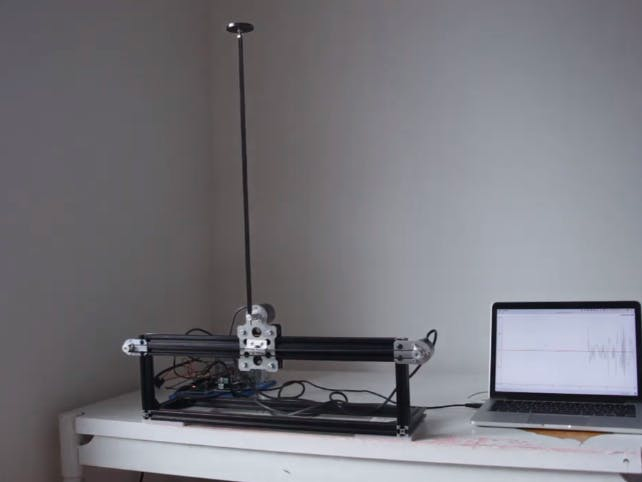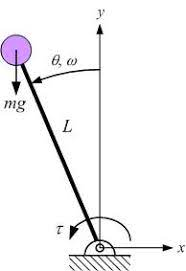


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}\left(\theta \right)=\omega \\
\frac{\mathrm{d}}{\mathrm{d}t}\left(\omega \right)=\frac{g}{l}\sin \left(\theta \right)-\frac{b}{{m\;l}^2 }\omega 
\end{array}$$


ใช้ฟังก์ชัน `ode45` ในการแก้สมการเชิงอนุพันธ์

m = 1;
l = 1;
b = 1;
g = 9.80665;
t_max = 10;
x_0 = [pi/2; 0]; % เงื่อนไขเริ่มต้น Initial Condition
[t,x] = ode45( @ ...
    (t,x)[x(2); ...
    (g/l)*sin(x(1))-(b/(m*l^2))*x(2)], ...
    [0 t_max], ...
    x_0);
plot(t,x(:,1)) % แสดงผลของการแก้สมการในกราฟ

## สร้าง Animation

สร้างแอนิเมชันจากการคำนวณผลลัพธ์ที่ได้

ax = axes;
hold(ax, 'on');
axis(ax, [-1.5 1.5 -1.5 0.5]); % กำหนดขอบเขตของกราฟ
plot(ax, [-2 2], [0 0], 'k', 'LineWidth', 3); % วาดเส้นพื้นฐาน

for i = 1:numel(t)-1
    theta = x(i, 1); % ดึงค่า theta ที่ได้จากการแก้สมการ
    h = plot(ax, [0 l*sin(theta)], [0 l*cos(theta)], 'b', 'LineWidth', 3); % วาดกราฟตำแหน่งของจุดที่เคลื่อนไหว
    dt = t(i+1) - t(i); % คำนวณเวลาหยุดชั่วคราว
    pause(dt); % หยุดชั่วคราวตามเวลาที่คำนวณ
    delete(h); % ลบกราฟที่วาดเพื่อวาดกราฟใหม่
end

theta = x(end, 1);
h = plot(ax, [0 l*sin(theta)], [0 l*cos(theta)], 'b', 'LineWidth', 3); % วาดกราฟสุดท้าย

## ตัวอย่างการจำลองการเคลื่อนที่แบบ Projectile

การจำลองการเคลื่อนที่แบบ Projectile สามารถทำได้ใน MATLAB โดยการใช้สมการเชิงอนุพันธ์ที่เกี่ยวข้องกับการเคลื่อนที่แบบพาราโบลา ในตัวอย่างนี้จะมีสองแบบ:

- **แบบ Kinematics** (ไม่คิดแรงต้านอากาศ)

- **แบบ Dynamics** (คิดแรงต้านอากาศและมวล)

### **ตัวอย่างที่ 1: Kinematics (ไม่คิดแรงต้านอากาศ)**

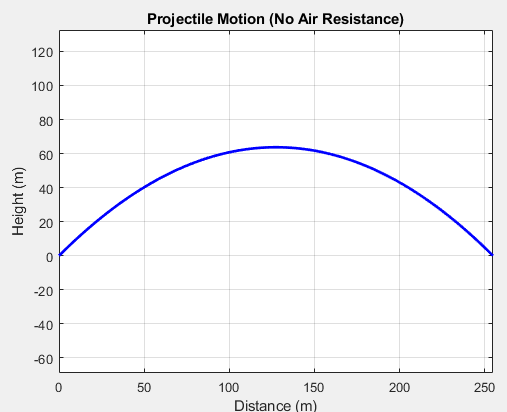

ในกรณีนี้ เราจะใช้สมการการเคลื่อนที่แบบพาราโบลา (projectile motion) ที่ไม่คิดแรงต้านอากาศ:

`ตำแหน่งในแนวราบ `$x\left(t\right)\;=v_0 \cos \left(\theta \right)t$

ตำแหน่งในแนวดิ่ง $y\left(t\right)=v_{0\;} \sin \left(\theta \right)t-\frac{1}{2}{\textrm{gt}}^2$

โดยที่ $v_0$ คือความเร็วต้น $\theta \;$ คือมุมยิงที่กระทำกับแนวราบ $g$ คือความเร่งเนื่องจากแรงโน้มถ่วง

% Parameters
v0 = 50; % Initial speed in m/s
theta = 45; % Angle in degrees
g = 9.81; % Acceleration due to gravity in m/s^2

% Time vector
t = linspace(0, 2*v0*sin(deg2rad(theta))/g, 100);

% Kinematic equations for projectile motion
x = v0 * cos(deg2rad(theta)) * t;
y = v0 * sin(deg2rad(theta)) * t - 0.5 * g * t.^2;

% Plotting the trajectory
figure;
plot(x, y, 'b-', 'LineWidth', 2);
xlabel('Distance (m)');
ylabel('Height (m)');
title('Projectile Motion (No Air Resistance)');
grid on;
axis equal;

### **ตัวอย่างที่ 2: Dynamics (คิดแรงต้านอากาศและมวล)**

ในการจำลองการเคลื่อนที่แบบโปรเจกไทล์โดยคำนึงถึงแรงต้านอากาศ (Dynamics) สมการการเคลื่อนที่จะประกอบด้วยแรงโน้มถ่วงและแรงต้านอากาศ ซึ่งจะมีผลต่อการเร่งความเร็วในทั้งสองทิศทาง (แนวนอนและแนวตั้ง) ดังนี้:

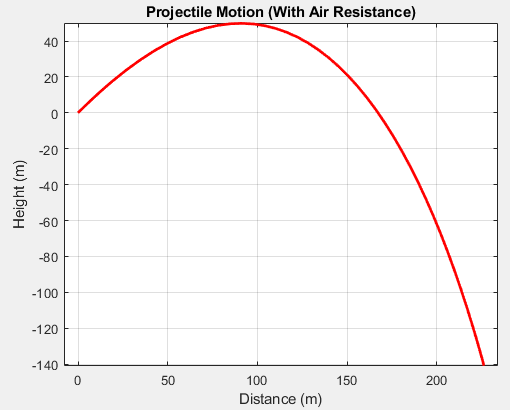

#### **1. ****แรงโน้มถ่วง (Gravity Force)**

แรงโน้มถ่วง $g$ จะกระทำในทิศทางแนวดิ่งลง (แกน $y$) โดยมีค่าเท่ากับ $g=9\ldotp 81\;\frac{m}{s^2 }$ ซึ่งทำให้เกิดการเร่งความเร็วในแนวดิ่งลง


$$F_g =\textrm{mg}$$


#### **2. แรงต้านอากาศ (Drag Force)**

แรงต้านอากาศ $F_d$ จะกระทำในทิศทางตรงข้ามกับทิศทางการเคลื่อนที่ของวัตถุในทุกทิศทาง ซึ่งมีค่าเป็นสัดส่วนกับความเร็วสัมพัทธ์ $v$ ของวัตถุ:


$$F_d =\frac{1}{2}C_d \rho {\textrm{Av}}^2$$


โดยที่     $C_d \;\textrm{คือ}\;\textrm{สัมประสิทธิ์แรงต้านอากาศ}$

              
$$\rho \;\textrm{คือ}\;\textrm{ความหนาแน่นของอากาศ}$$


              $A$ คือ พื้นที่หน้าตัดของวัตถุ

              $v$ คือ ความเร็วของวัตถุ

#### 3. สมการเคลื่อนที่แบบ Dynamics

เมื่อพิจารณาถึงแรงต้านอากาศ สมการการเคลื่อนที่จะเป็นสมการเชิงอนุพันธ์ในแต่ละทิศทาง (แกน $x$ และแกน $y$) ดังนี้:

**ในแนวแกน **$x$** (Horizontal Direction):**


$$\frac{{\textrm{dv}}_x }{\textrm{dt}}=-\frac{1}{2}*\frac{C_d \rho \;A}{m}*v*v_x$$


**ในแนวแกน **$y$** (Vertical Direction):**


$$\frac{{\textrm{dv}}_y }{\textrm{dt}}=-g-\frac{1}{2}*\frac{C_d \rho \;A}{m}*v*v_y$$


โดยที่       $v_x \;\textrm{และ}\;v_y \;\textrm{คือความเร็วในแนวแกน}\;x\;\textrm{และ}\;y\;\textrm{ตามลำดับ}$


$$v=\sqrt{{v_x }^2 +{v_y }^2 }$$


#### 4. สมการการเคลื่อนที่

เมื่อรวมสมการทั้งหมดจะได้สมการดังต่อไปนี้


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=v_x \\
\frac{\textrm{dy}}{\textrm{dt}}=v_y \\
\frac{{\textrm{dv}}_x }{\textrm{dt}}=-\frac{1}{2}*\frac{C_d \rho \;A}{m}*v*v_x \\
\frac{{\textrm{dv}}_y }{\textrm{dt}}=-g-\frac{1}{2}*\frac{C_d \rho \;A}{m}*v*v_y 
\end{array}$$


เมื่อพิจารณาถึงแรงต้านอากาศ สมการการเคลื่อนที่จะเป็นสมการเชิงอนุพันธ์ในแต่ละทิศทาง (แกน $x$ และแกน $y$) ดังนี้:

% Parameters
v0 = 50; % Initial speed in m/s
theta = 45; % Angle in degrees
g = 9.81; % Acceleration due to gravity in m/s^2
m = 1; % Mass of the projectile in kg
Cd = 0.47; % Drag coefficient (sphere)
rho = 1.225; % Air density in kg/m^3
A = 0.01; % Cross-sectional area in m^2

% Initial conditions
vx0 = v0 * cos(deg2rad(theta)); % Initial velocity in x
vy0 = v0 * sin(deg2rad(theta)); % Initial velocity in y
initial_conditions = [0, 0, vx0, vy0]; % [x0, y0, vx0, vy0]

% Time span
tspan = [0, 10];

% Differential equation solver
projectile_dynamics = @(t, y) [y(3); y(4); -0.5 * Cd * rho * A * sqrt(y(3)^2 + y(4)^2) * y(3) / m; ...
                               -g - 0.5 * Cd * rho * A * sqrt(y(3)^2 + y(4)^2) * y(4) / m];
[t, sol] = ode45(projectile_dynamics, tspan, initial_conditions);

% Extracting the solutions
x = sol(:, 1);
y = sol(:, 2);

% Plotting the trajectory
figure;
plot(x, y, 'r-', 'LineWidth', 2);
xlabel('Distance (m)');
ylabel('Height (m)');
title('Projectile Motion (With Air Resistance)');
grid on;
axis equal;

### **ตัวอย่างที่ 3: เปรียบเทียบการเคลื่อนที่ระหว่าง Kinematics VS Dynamics (คิดแรงต้านอากาศและมวล)**

การเปรียบเทียบกราฟของการเคลื่อนที่แบบ Projectile ทั้งสองแบบ: แบบ Kinematics (ไม่คิดแรงต้านอากาศ) และแบบ Dynamics (คิดแรงต้านอากาศและมวล) โดยวาดกราฟทั้งสองลงบนกราฟเดียวกันเพื่อเปรียบเทียบ:

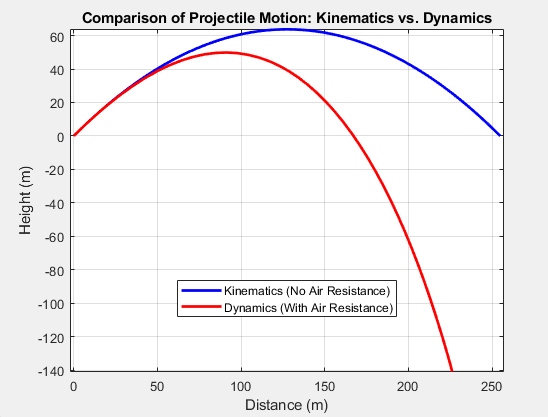

% Parameters
v0 = 50; % Initial speed in m/s
theta = 45; % Angle in degrees
g = 9.81; % Acceleration due to gravity in m/s^2
m = 1; % Mass of the projectile in kg
Cd = 0.47; % Drag coefficient (sphere)
rho = 1.225; % Air density in kg/m^3
A = 0.01; % Cross-sectional area in m^2

% Time vector for kinematics (assuming maximum time based on range)
t_kinematics = linspace(0, 2*v0*sin(deg2rad(theta))/g, 100);

% Kinematic equations for projectile motion (No Air Resistance)
x_kinematics = v0 * cos(deg2rad(theta)) * t_kinematics;
y_kinematics = v0 * sin(deg2rad(theta)) * t_kinematics - 0.5 * g * t_kinematics.^2;

% Initial conditions for dynamics (With Air Resistance)
vx0 = v0 * cos(deg2rad(theta)); % Initial velocity in x
vy0 = v0 * sin(deg2rad(theta)); % Initial velocity in y
initial_conditions = [0, 0, vx0, vy0]; % [x0, y0, vx0, vy0]

% Time span for dynamics
tspan = [0, 10];

% Define the dynamics function as an anonymous function
projectile_dynamics = @(t, y) [y(3); y(4); -0.5 * Cd * rho * A * sqrt(y(3)^2 + y(4)^2) * y(3) / m; ...
                               -g - 0.5 * Cd * rho * A * sqrt(y(3)^2 + y(4)^2) * y(4) / m];

% Differential equation solver for dynamics
[t_dynamics, sol] = ode45(projectile_dynamics, tspan, initial_conditions);

% Extracting the solutions for dynamics
x_dynamics = sol(:, 1);
y_dynamics = sol(:, 2);

% Plotting the trajectories for comparison
figure;
plot(x_kinematics, y_kinematics, 'b-', 'LineWidth', 2, 'DisplayName', 'Kinematics (No Air Resistance)');
hold on;
plot(x_dynamics, y_dynamics, 'r-', 'LineWidth', 2, 'DisplayName', 'Dynamics (With Air Resistance)');
xlabel('Distance (m)');
ylabel('Height (m)');
title('Comparison of Projectile Motion: Kinematics vs. Dynamics');
legend('Location', 'best');
grid on;
axis equal;
hold off;

กราฟที่ได้จะแสดงให้เห็นความแตกต่างระหว่างการเคลื่อนที่แบบไม่มีแรงต้านอากาศ (Kinematics) และแบบมีแรงต้านอากาศ (Dynamics) ซึ่งจะทำให้วิถีของ projectile ลดลงเนื่องจากแรงต้านอากาศ